clear all

% Params
fs = 8e3;

% 1 - LP IIR filter design
% Spec - filterDesigner
% 2 - BP IIR filter design
% Spec - filterDesigner
% 3 - HP IIR filter design
% Spec - filterDesigner

% 4 
load('LP_Filter_60.mat')
[LP_B, LP_A] = sos2tf(SOS_LP_60, G_LP_60)

LP_B =     0.0061   -0.0000    0.0397    0.0199    0.1266    0.1179    0.2888    0.3402    0.5365    0.6502    0.8200    0.9288    1.0170    1.0414    1.0170    0.9288    0.8200    0.6502    0.5365    0.3402    0.2888    0.1179    0.1266    0.0199    0.0397   -0.0000    0.0061


LP_A =     1.0000   -4.1594   13.0255  -27.0028   47.2348  -64.6172   78.1763  -77.5290   70.2768  -52.4136   37.2750  -20.8793   12.2765   -4.8019    2.6956   -0.4845    0.4864    0.0714    0.1042    0.0447    0.0257    0.0117    0.0051    0.0019    0.0006    0.0002    0.0000


%fvtool(LP_B,LP_A)

% 5 
load('BP_Filter_60.mat')
[BP_B, BP_A] = sos2tf(SOS_BP_60, G_BP_60)

BP_B =     0.0056   -0.0000   -0.0000   -0.0000    0.0182   -0.0000   -0.0091    0.0000    0.0284   -0.0000   -0.0247   -0.0000    0.0319    0.0000   -0.0319    0.0000    0.0247         0   -0.0284    0.0000    0.0091    0.0000   -0.0182         0    0.0000    0.0000   -0.0056


BP_A =     1.0000    0.0000    4.0650    0.0000    9.3188    0.0000   14.0955    0.0000   15.6905    0.0000   13.1838   -0.0000    8.6268   -0.0000    4.3702   -0.0000    1.7298   -0.0000    0.5160   -0.0000    0.1162   -0.0000    0.0174   -0.0000    0.0019   -0.0000    0.0000


%fvtool(BP_B,BP_A)

% 6
load('HP_Filter_60.mat')
[HP_B, HP_A] = sos2tf(SOS_HP_60, G_HP_60)

HP_B =     0.0061    0.0000    0.0397   -0.0199    0.1266   -0.1179    0.2888   -0.3402    0.5365   -0.6502    0.8200   -0.9288    1.0170   -1.0414    1.0170   -0.9288    0.8200   -0.6502    0.5365   -0.3402    0.2888   -0.1179    0.1266   -0.0199    0.0397    0.0000    0.0061


HP_A =     1.0000    4.1594   13.0255   27.0028   47.2348   64.6172   78.1763   77.5290   70.2768   52.4136   37.2750   20.8793   12.2765    4.8019    2.6956    0.4845    0.4864   -0.0714    0.1042   -0.0447    0.0257   -0.0117    0.0051   -0.0019    0.0006   -0.0002    0.0000


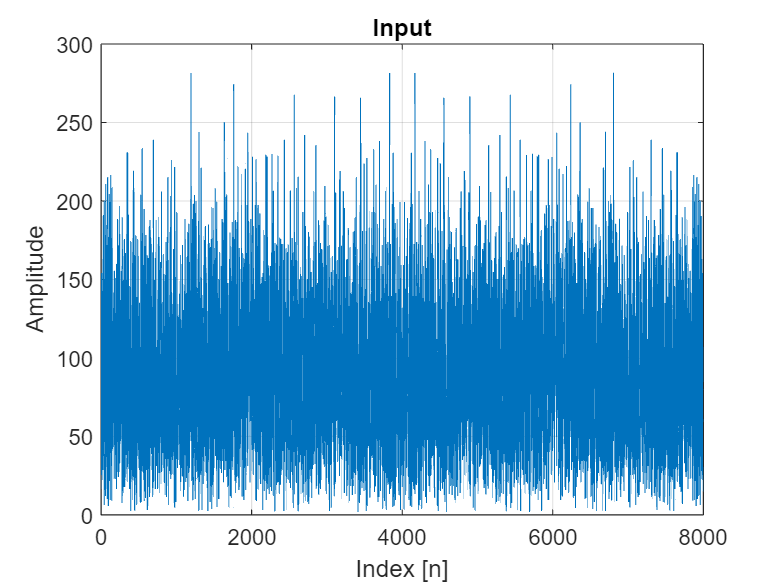

%fvtool(HP_B,HP_A)

% 16 - LP quant PZ
q_float = quantizer('single'); % Convert to signle precision
LP_A_q_float = quantize(q_float, LP_A);
LP_B_q_float = quantize(q_float, LP_B);
%fvtool(LP_B_q_float, LP_A_q_float)

% q_fixed = quantizer('DataMode', 'fixed', 'OverflowMode', 'saturate', Format=[10 7]); % Convert to fixed
% LP_A_q_fixed = quantize(q_fixed, LP_A);
% LP_B_q_fixed = quantize(q_fixed, LP_B);
% fvtool(LP_B_q_fixed, LP_A_q_fixed)
% q_fixed = quantizer(DataMode='fixed', OverflowMode='saturate',Format=[32 16]); % Convert to fixed
% LP_A_q_fixed = quantize(q_fixed, LP_A);
% LP_B_q_fixed = quantize(q_fixed, LP_B);
% fvtool(LP_B_q_fixed, LP_A_q_fixed)
% q_fixed = quantizer(DataMode='fixed', OverflowMode='saturate',Format=[16 15]); % Convert to fixed
% LP_A_q_fixed = quantize(q_fixed, LP_A);
% LP_B_q_fixed = quantize(q_fixed, LP_B);
% fvtool(LP_B_q_fixed, LP_A_q_fixed)
% q_fixed = quantizer(DataMode='fixed', OverflowMode='saturate',Format=[16 14]); % Convert to fixed
% LP_A_q_fixed = quantize(q_fixed, LP_A);
% LP_B_q_fixed = quantize(q_fixed, LP_B);
% fvtool(LP_B_q_fixed, LP_A_q_fixed)
% q_fixed = quantizer(DataMode='fixed', OverflowMode='saturate',Format=[16 13]); % Convert to fixed
% LP_A_q_fixed = quantize(q_fixed, LP_A);
% LP_B_q_fixed = quantize(q_fixed, LP_B);
% fvtool(LP_B_q_fixed, LP_A_q_fixed)
% q_fixed = quantizer(DataMode='fixed', OverflowMode='saturate',Format=[16 12]); % Convert to fixed
% LP_A_q_fixed = quantize(q_fixed, LP_A);
% LP_B_q_fixed = quantize(q_fixed, LP_B);
% fvtool(LP_B_q_fixed, LP_A_q_fixed)
% q_fixed = quantizer(DataMode='fixed', OverflowMode='saturate',Format=[16 11]); % Convert to fixed
% LP_A_q_fixed = quantize(q_fixed, LP_A);
% LP_B_q_fixed = quantize(q_fixed, LP_B);
% fvtool(LP_B_q_fixed, LP_A_q_fixed)
% q_fixed = quantizer(DataMode='fixed', OverflowMode='saturate',Format=[16 10]); % Convert to fixed
% LP_A_q_fixed = quantize(q_fixed, LP_A);
% LP_B_q_fixed = quantize(q_fixed, LP_B);
% fvtool(LP_B_q_fixed, LP_A_q_fixed)
% q_fixed = quantizer(DataMode='fixed', OverflowMode='saturate',Format=[16 9]); % Convert to fixed
% LP_A_q_fixed = quantize(q_fixed, LP_A);
% LP_B_q_fixed = quantize(q_fixed, LP_B);
% fvtool(LP_B_q_fixed, LP_A_q_fixed)
% q_fixed = quantizer(DataMode='fixed', OverflowMode='saturate',Format=[16 8]); % Convert to fixed
% LP_A_q_fixed = quantize(q_fixed, LP_A);
% LP_B_q_fixed = quantize(q_fixed, LP_B);
% fvtool(LP_B_q_fixed, LP_A_q_fixed)

% 17 - BP quant PZ
q_float = quantizer('single'); % Convert to signle precision
BP_A_q_float = quantize(q_float, BP_A);
BP_B_q_float = quantize(q_float, BP_B);
%fvtool(BP_B_q_float, BP_A_q_float)

% 18 - HP quant PZ
q_float = quantizer('single'); % Convert to signle precision
HP_A_q_float = quantize(q_float, HP_A);
HP_B_q_float = quantize(q_float, HP_B);
%fvtool(HP_B_q_float, HP_A_q_float)

% 19 - LP WGN Frq
x = wgn(10000,1,0); % Gaussian noise (mean = 0, std = 1)

figure;
plot(fs*[0:1/length(x):(length(x)-1)/length(x)], abs(fft(x)));
xlabel('Index [n]');
ylabel('Amplitude');
title('Input');
grid on;

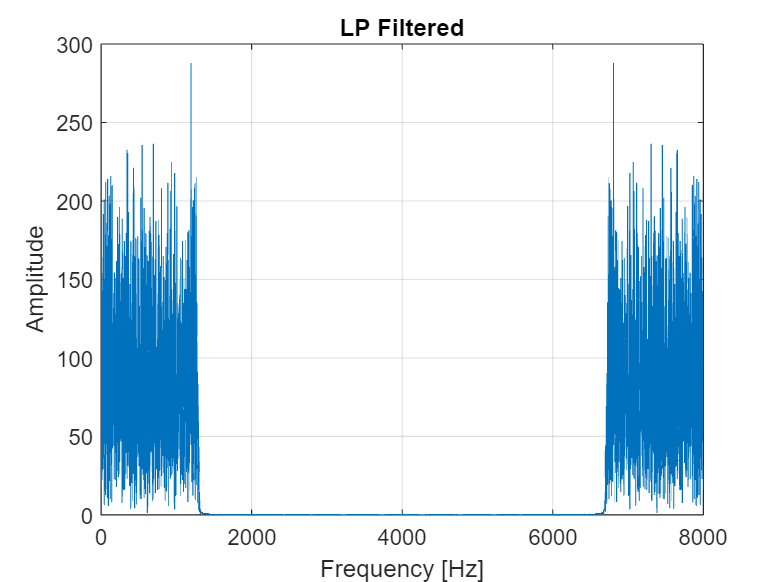


y_lp = filter(LP_B_q_float, LP_A_q_float, x);

figure;
plot(fs*[0:1/length(y_lp):(length(y_lp)-1)/length(y_lp)], abs(fft(y_lp)));
xlabel('Frequency [Hz]');
ylabel('Amplitude');
title('LP Filtered'); % Two-sided
grid on;

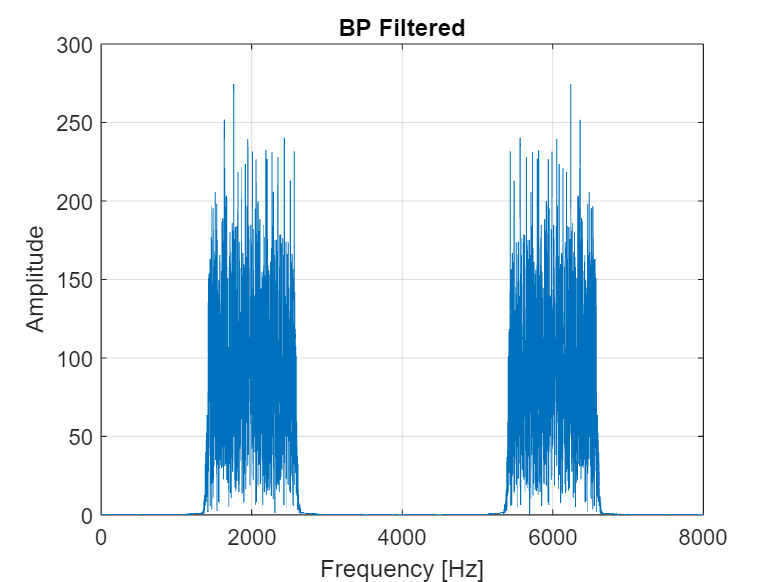


% 20 - BP WGN Frq
y_bp = filter(BP_B_q_float, BP_A_q_float, x);

figure;
plot(fs*[0:1/length(y_bp):(length(y_bp)-1)/length(y_bp)], abs(fft(y_bp)));
xlabel('Frequency [Hz]');
ylabel('Amplitude');
title('BP Filtered'); % Two-sided
grid on;

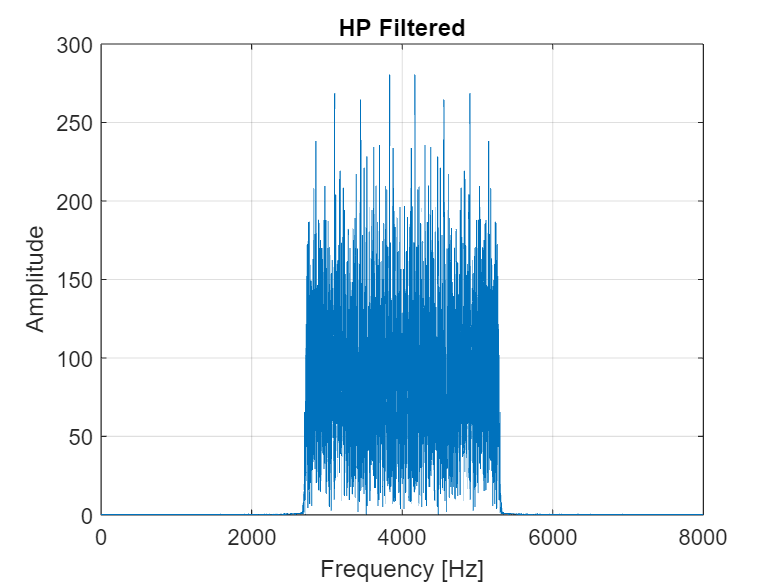


% 21 - HP WGN Frq
y_hp = filter(HP_B_q_float, HP_A_q_float, x);

figure;
plot(fs*[0:1/length(y_hp):(length(y_hp)-1)/length(y_hp)], abs(fft(y_hp)));
xlabel('Frequency [Hz]');
ylabel('Amplitude');
title('HP Filtered'); % Two-sided
grid on;

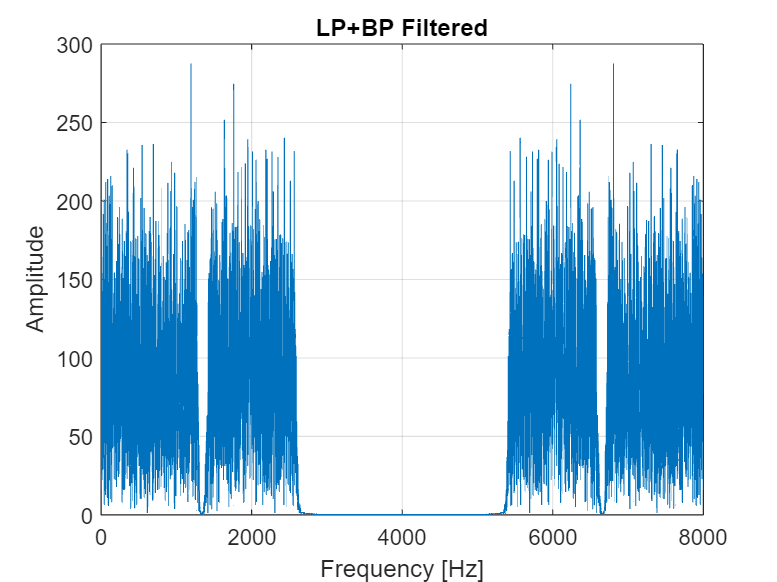


% 22 - LP+BP WGN Frq
y_lp = filter(LP_B_q_float, LP_A_q_float, x);
y_bp = filter(BP_B_q_float, BP_A_q_float, x);
y_lp_bp = y_lp+y_bp;

figure;
plot(fs*[0:1/length(y_lp_bp):(length(y_lp_bp)-1)/length(y_lp_bp)], abs(fft(y_lp_bp)));
xlabel('Frequency [Hz]');
ylabel('Amplitude');
title('LP+BP Filtered'); % Two-sided
grid on;

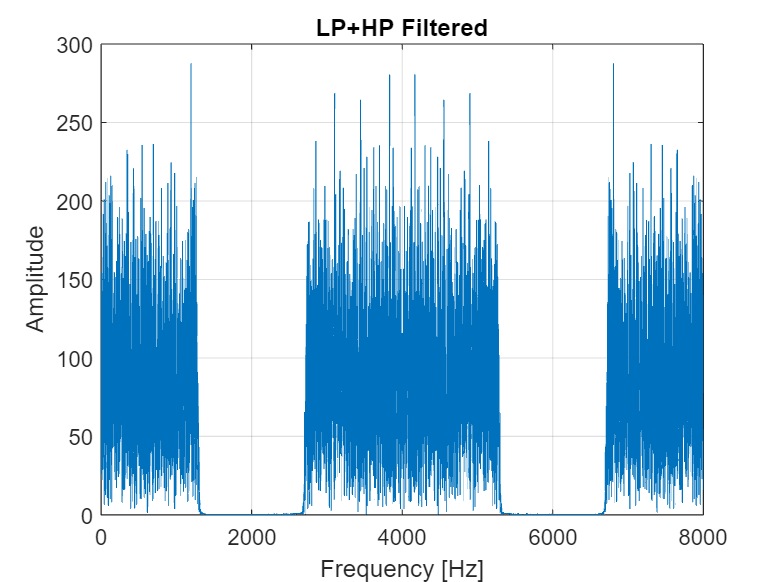

% 23 - LP+HP WGN Frq
y_lp = filter(LP_B_q_float, LP_A_q_float, x);
y_hp = filter(HP_B_q_float, HP_A_q_float, x);
y_lp_hp = y_lp+y_hp;

figure;
plot(fs*[0:1/length(y_lp_hp):(length(y_lp_hp)-1)/length(y_lp_hp)], abs(fft(y_lp_hp)));
xlabel('Frequency [Hz]');
ylabel('Amplitude');
title('LP+HP Filtered'); % Two-sided
grid on;

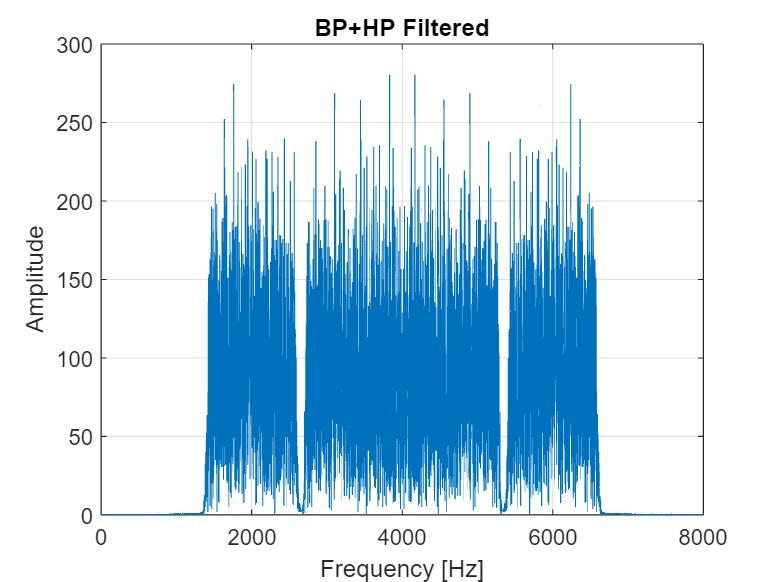


% 24 - BP+HP WGN Frq
y_bp = filter(BP_B_q_float, BP_A_q_float, x);
y_hp = filter(HP_B_q_float, HP_A_q_float, x);
y_bp_hp = y_bp+y_hp;

figure;
plot(fs*[0:1/length(y_bp_hp):(length(y_bp_hp)-1)/length(y_bp_hp)], abs(fft(y_bp_hp)));
xlabel('Frequency [Hz]');
ylabel('Amplitude');
title('BP+HP Filtered'); % Two-sided
grid on;

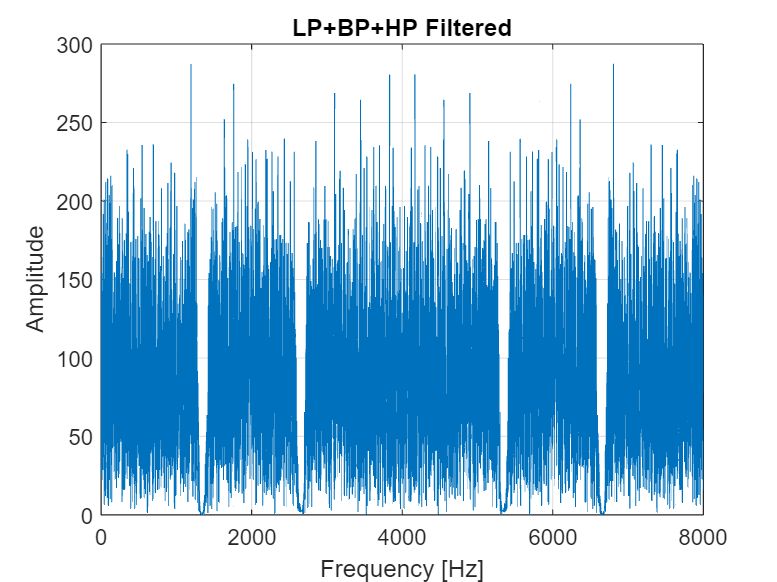


% 25 - BP+HP WGN Frq
y_lp = filter(LP_B_q_float, LP_A_q_float, x);
y_bp = filter(BP_B_q_float, BP_A_q_float, x);
y_hp = filter(HP_B_q_float, HP_A_q_float, x);
y_lp_bp_hp = y_lp+y_bp+y_hp;

figure;
plot(fs*[0:1/length(y_lp_bp_hp):(length(y_lp_bp_hp)-1)/length(y_lp_bp_hp)], abs(fft(y_lp_bp_hp)));
xlabel('Frequency [Hz]');
ylabel('Amplitude');
title('LP+BP+HP Filtered'); % Two-sided
grid on;

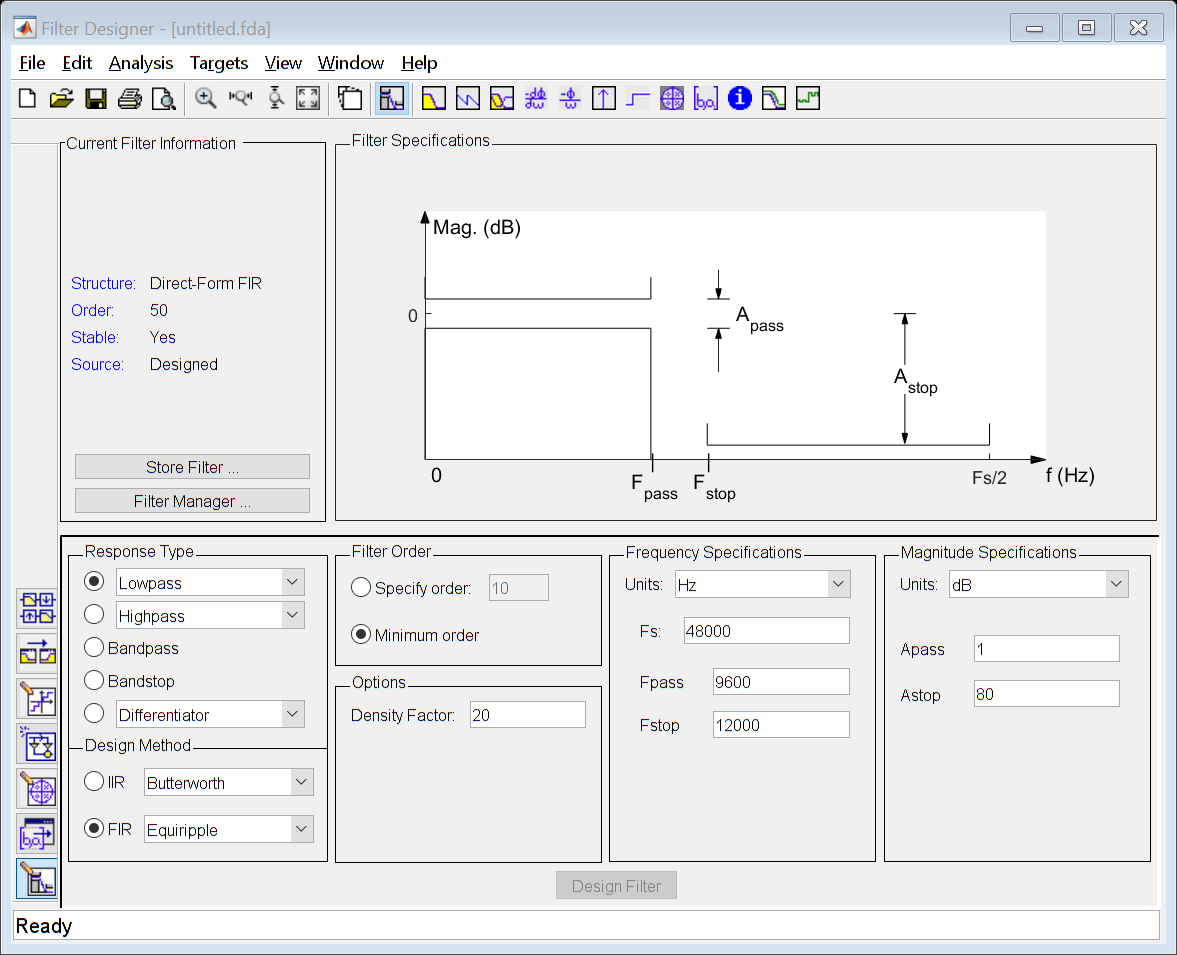

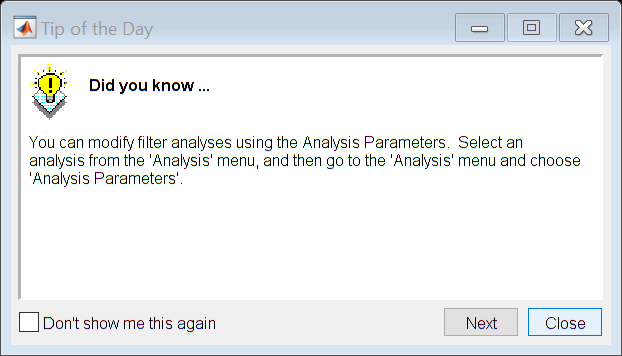

filterDesigner